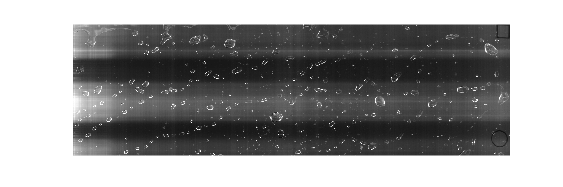

% Get image for analyzing
img_source = im2gray(imread('_IMAG0003.JPG'));
imshow(img_source)

relImg = double(img_source)./256;

### Radon transformation

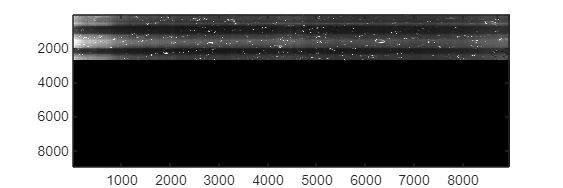

I = zeros(8960,8960); % 16384*16384

I(1:2688,1:8960) = relImg;
imagesc(I,[0 1]);
colormap(gray);


theta = 0:179;
[R,xp] = radon(I,theta);

% imshow(R,[],'Ydata',theta,'Xdata',xp,'InitialMagnification','fit')
% ylabel('\theta (degrees)')
% xlabel('x''')
% colormap(gca,hot), colorbar
% 
% iptsetpref('ImshowAxesVisible','off')

### Radon filtering

R_filtered = R;

% ANGLE FOR FILTERING
% angle range
delta_angle = 1;

angle_filtered = [1,178,179];


% get mean value
r_value = quantile(R_filtered(:,angle_filtered),0.75,"all")

r_value = 653.1964


% delete lines
R_filtered(:,angle_filtered) = r_value;

img_filtered = iradon(R_filtered,theta,'spline','Shepp-Logan');

% try to use other filters ('None' gives blurred image)
%img_filtered = iradon(R_filtered,theta,'spline','Hann');
%imagesc(img_filtered);

### Grayscale image

img_filtered = img_filtered(1:2688,1:8960);
min_val = min(img_filtered(:))

min_val = -3.3208

max_val = max(img_filtered(:))

max_val = 3.8863

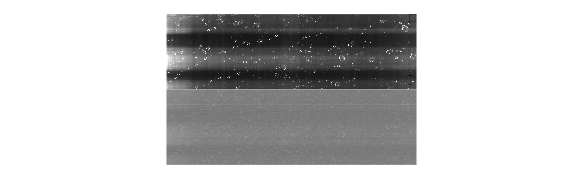

img_grayscale = uint8(255/(max_val-min_val)*(img_filtered-min_val));
montage({img_source, img_grayscale},'Size', [2 1]);

### Contrast enchancement

% contrast enchancement
img = imlocalbrighten(img_grayscale);
img = imreducehaze(img);
img = wiener2(img);

img = localcontrast(img);
%img = imadjust(img);

montage({img_grayscale, img},'Size', [2 1]);

### Binarization

threshold = 80;
% relative intensity
relThresh = threshold/256;

bw = imbinarize(img,relThresh);
bw = bwareaopen(bw,50);
bw = imclearborder(bw);

% close mask with disk
%se = strel('disk',5,4)
%bw = imclose(bw, se);
bw = imfill(bw, 'holes');

montage({img_source, bw},'Size', [2 1]);

### FFT transformation

F = fft2(img_source);

### Show FFT image

imagesc(100*log(1+abs(fftshift(F)))); colormap(gray); 
title('magnitude spectrum');

figure;
imagesc(angle(F));  colormap(gray);
title('phase spectrum');

### IFFT transformation

img_filtered = ifft2(F);